wd=pwd;
ExperimentName=wd(30:end);
analysis_name=[ExperimentName,'_analysis_'];

number_of_acq = 24;
max_points_all=[];
photoncount_all=[];
histograms_39=[];
histograms_40=[];
histograms_41=[];
histograms_42=[];
histograms_43=[];

for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'h.mat'];
    load(filename)
    eval(['max_points_',num2str(i),'=zeros(1, size(lifetime_histograms, 2));'])
    for j=1:size(lifetime_histograms, 2)
        single_histogram=lifetime_histograms(:,j);
        eval(['max_points_',num2str(i),'(',num2str(j),')=mean(find(single_histogram==max(single_histogram)));'])
        
        if find(single_histogram==max(single_histogram))==39
            histograms_39=[histograms_39 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==40
            histograms_40=[histograms_40 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==41
            histograms_41=[histograms_41 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==42
            histograms_42=[histograms_42 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==43
            histograms_43=[histograms_43 single_histogram/max(single_histogram)];
        end
    end
    eval(['max_points_all=[max_points_all max_points_',num2str(i),'];'])
    photoncount_all=[photoncount_all photoncount'];
%     figure
%     eval(['histogram(max_points_',num2str(i),')'])
    
end

save([ExperimentName,'_peaks.mat'])

dark_hours=[15 16 17 18 19 20 21 22 23 24 25]

dark_hours =     15    16    17    18    19    20    21    22    23    24    25


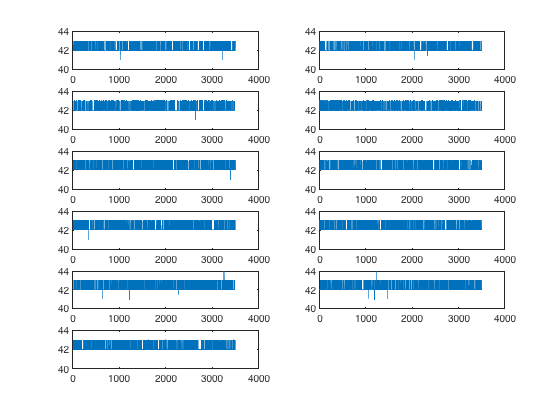

first_acq=13;

for i=1:size(dark_hours,2)
    subplot(ceil(size(dark_hours,2)/2),2,i)
    eval(['plot(max_points_',num2str(dark_hours(i)-first_acq+1),')'])
    ylim([40 44])
end

[n, xout]=hist(max_points_all)

n =           20           2           0       68762         126           0       15047           0           0           4


xout =   41.149999999999999  41.449999999999996  41.750000000000000  42.049999999999997  42.350000000000001  42.649999999999999  42.949999999999996  43.250000000000000  43.549999999999997  43.850000000000001


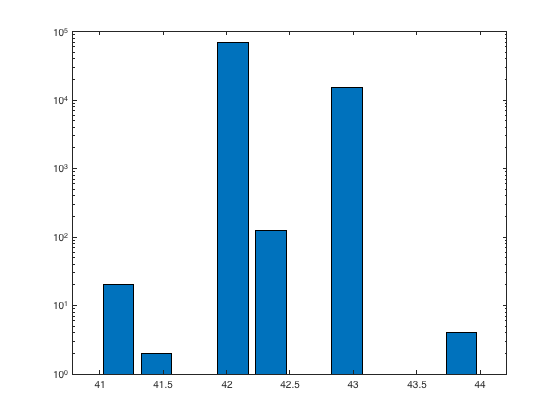

figure
bar(xout, n)
set(gca,'YScale','log')

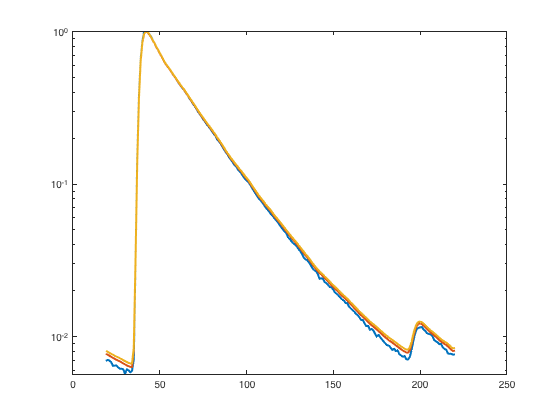

histograms_40=histograms_40';
histograms_41=histograms_41';
histograms_42=histograms_42';
histograms_43=histograms_43';

figure
% semilogy(mean(histograms_40(:,1:220)),'LineWidth',2)
% hold on
semilogy(mean(histograms_41(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_42(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_43(:,1:220)),'LineWidth',2)